% cd 'C:\GitHub\CVUT-MatLab\BnB'
clear;clc;startup;yalmip('clear')

Toolbox "yalmip:R20230609:all" added to the Matlab path.

The MATLAB interface for Gurobi 10.0.3 has been installed.

The directory
    C:\Program Files\MATLAB\Gurobi\win64\matlab\
has been added to the MATLAB path.
To use Gurobi regularly, you must save this new path definition.
To do this, type the command
    savepath
at the MATLAB prompt. Please consult the MATLAB documentation
if necessary.


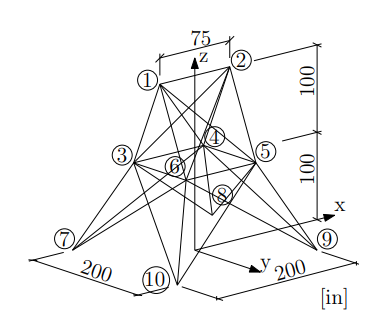

% crossSectionsSet = ((1:34)*0.1)';
crossSectionsSet = ((15:34)*0.1)';
na = numel(crossSectionsSet);

## Ground structure

### Nodes

nodes.x = [-37.5; 37.5; -37.5; 37.5; 37.5; -37.5; -100; 100; 100; -100];                       % x coordinates of nodes
nodes.y = [0; 0; -37.5; -37.5; 37.5; 37.5; -100; -100; 100; 100];                       % y coordinates of nodes
nodes.z = [200; 200; 100; 100; 100; 100; 0; 0; 0; 0];                       % z coordinates of nodes
nnodes  = numel(nodes.x);                           % number of nodes

### Elements

elements.nodes1 = [1;1;2;1;2;2;2;1;1;3;4;3;5; 3;6;4;5;3;4;6; 5;3;4;5; 6];   % elements starting nodes
elements.nodes2 = [2;4;3;5;6;5;4;3;6;6;5;4;6;10;7;9;8;8;7;9;10;7;8;9;10];   % elements ending nodes
nr = numel(elements.nodes1);  % number of elements  

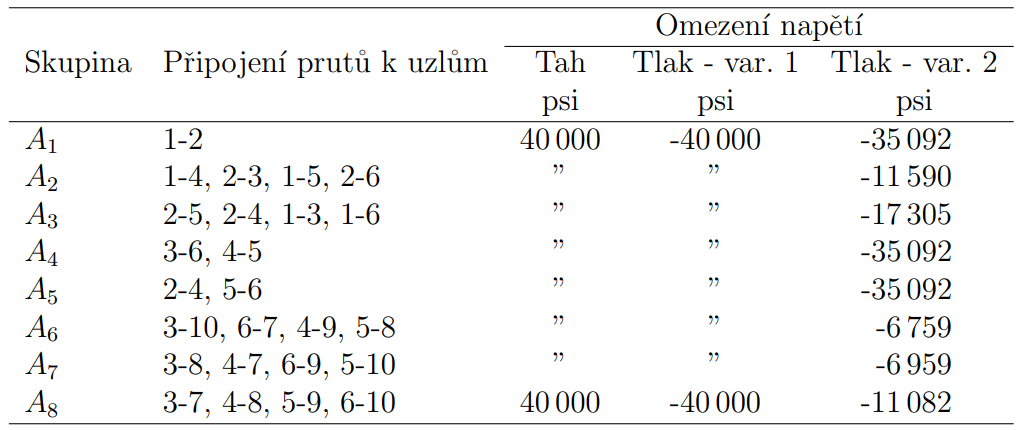

### Groups of elements

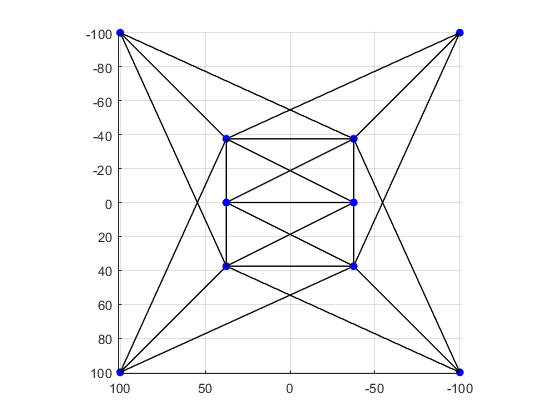

elemGroup = [1;2;2;2;2;3;3;3;3;4;4;5;5;6;6;6;6;7;7;7;7;8;8;8;8];
ng = max(elemGroup);

plot3([nodes.x(elements.nodes1) nodes.x(elements.nodes2)]', ...
     [nodes.y(elements.nodes1) nodes.y(elements.nodes2)]', ...
     [nodes.z(elements.nodes1) nodes.z(elements.nodes2)]', ...
     'k','LineWidth',1);
hold on;
scatter3(nodes.x, nodes.y, nodes.z, 'blue', 'filled', 'o');
axis equal;
xlim([min(nodes.x)-1,max(nodes.x)+1]);  % to avoid tight limits
ylim([min(nodes.y)-1,max(nodes.y)+1]);  % to avoid tight limits
zlim([min(nodes.z)-1,max(nodes.z)+1]);  % to avoid tight limits
grid on
view([180 90])
hold off;

### Material and cross-section

elements.E = 10^4 ;    % Young moduli of individual elements
elements.Rho = 0.1 ;    

## Boundary conditions

### Restricted displacements

kinematic.x.nodes = [7;8;9;10];             % node indices with restricted x-direction displacements
kinematic.y.nodes = [7;8;9;10];             % node indices with restricted y-direction displacements
kinematic.z.nodes = [7;8;9;10];          % node indices with restricted z-direction displacements

### Load

loads.x.nodes = [1;2;3;6];             % node indices with x-direction forces
loads.x.value = [1;0;0.5;0.6];             % magnitude of the x-direction forces
loads.y.nodes = [1;2;3;6];          % node indices with y-direction forces
loads.y.value = [-10;-10;0;0];          % magnitude of the y-direction forces 
loads.z.nodes = [1;2;3;6];             % node indices with z-direction forces
loads.z.value = [-10;-10;0;0];             % magnitude of the z-direction forces 

### Boundary conditions

dofs = true(nnodes,3);                % no kinematic boundary conditions
dofs(kinematic.x.nodes,1) = false;    % mark prevented movement in x-direction
dofs(kinematic.y.nodes,2) = false;    % mark prevented movement in y-direction
dofs(kinematic.z.nodes,3) = false;    % mark prevented movement in z-direction
dofs = reshape(dofs.',[],1);
nd = sum(dofs,"all");

## Optimization parameters

maximumStress = 40;
minimumStress = -40;
maximumDisplacement = 0.35;
minimumDisplacement = -0.35;

### Design variables

x = binvar(ng*na,1);
% x = [0;0;0;0;1;0;0;0;0;0;1;0;0;0;0;0;0;0;0;0;0;0;0;0;0;1;0;0;0;0;0;1;0;0;0;0;0;0;0;0];
s = sdpvar(nr*na,1);
% s = [   0;0;0;0;2.97;0;0;0;0;0; ...
%         0.04;0;0;0;0;0;0;0;0;0; ...
%         0;0;0;0;0;2.87;0;0;0;0; ...
%         0;0.97;0;0;0;0;0;0;0;0; ...
%         0.03;0;0;0;0;0;0;0;0;0];
u = sdpvar(nd,1);  

## FEM

deltaX = nodes.x(elements.nodes2) - nodes.x(elements.nodes1);
deltaY = nodes.y(elements.nodes2) - nodes.y(elements.nodes1);
deltaZ = nodes.z(elements.nodes2) - nodes.z(elements.nodes1);
lengths = sqrt(deltaX.^2 + deltaY.^2 + deltaZ.^2);
cosinus = [deltaX./lengths deltaY./lengths deltaZ./lengths];
codeNumbers = [repmat(elements.nodes1,1,3) repmat(elements.nodes2,1,3)]*3-2 + repmat([0 1 2 0 1 2], nr, 1);
staticMatrix = sparse(codeNumbers(:), ...
                      repmat(1:nr,1,6), ...
                      [-cosinus(:,1); -cosinus(:,2); -cosinus(:,3); cosinus(:,1); cosinus(:,2); cosinus(:,3);], ...
                      nnodes*3, nr);
matrixB = full (staticMatrix(dofs,:) );

## Optimization problem formulation and solution

Fmin =  minimumStress * diag ( kron( ones(nr,1) , crossSectionsSet) );
Fmax =  maximumStress * diag ( kron( ones( nr,1) , crossSectionsSet) );
cmin = reshape((kron(elements.E*crossSectionsSet', 1 ./ lengths) .* (sum(((matrixB > 0) .* matrixB) .* minimumDisplacement)' + sum(((matrixB < 0) .* matrixB) .* maximumDisplacement)'))', 1, []);
Cmin = diag(cmin);
cmax = reshape((kron(elements.E*crossSectionsSet', 1 ./ lengths) .* (sum(((matrixB > 0) .* matrixB) .* maximumDisplacement)' + sum(((matrixB < 0) .* matrixB) .* minimumDisplacement)'))', 1, []);
Cmax = diag(cmax);
I = eye(nr * na);
B = kron(matrixB, ones(1, na));
K = kron ( kron ((elements.E./lengths), crossSectionsSet), ones(nd,1)') .* B';

Q = sparse(1:nr,elemGroup,1,nr,ng);
G = kron( Q, eye(na));
forceVector = sparse([loads.x.nodes*3-2; loads.y.nodes*3-1; loads.z.nodes*3], ...
                     1, ...
                     [loads.x.value; loads.y.value; loads.z.value ], ...
                     nnodes*3, 1);
f = forceVector(reshape(dofs.', 1, [])');
IM = zeros(nr, na * nr);
for j = 1:nr
        IM(j, na*(j-1)+1:na*(j)) = 1;
end


### Constraints

y = double2sdpvar(zeros(2*na*nr+ nd,1));
y(1:nr*na,1) = G*x;
y(1+nr*na:nr*na+nd,1) = u;
y(1+nr*na+nd:2*nr*na+nd,1) = s;

#### Constraint 1: Inequality


$$A_{ineq} y \leq b
$$


**Matrix **$A_{ineq}
$

Aineq = zeros(4*na*nr,2*nr*na+nd);

*First collumn*

Aineq(1:nr*na,1:nr*na)              =  Fmin;
Aineq(1+nr*na:2*nr*na,1:nr*na)      = -Fmax;
Aineq(1+2*nr*na:3*nr*na,1:nr*na)    = -Cmin;
Aineq(1+3*nr*na:4*nr*na,1:nr*na)    =  Cmax;

*Second collumn*

Aineq(1+2*nr*na:3*nr*na,1+nr*na:nr*na+nd)    =  K;
Aineq(1+3*nr*na:4*nr*na,1+nr*na:nr*na+nd)    = -K;

*Third collumn*

Aineq(1:nr*na,1+nr*na+nd:2*nr*na+nd)              = -I;
Aineq(1+nr*na:2*nr*na,1+nr*na+nd:2*nr*na+nd)      =  I;
Aineq(1+2*nr*na:3*nr*na,1+nr*na+nd:2*nr*na+nd)    =  I;
Aineq(1+3*nr*na:4*nr*na,1+nr*na+nd:2*nr*na+nd)    = -I;

**Vector **$b
$

b = zeros(4*na*nr,1);
b(1+2*nr*na:3*nr*na,1) = -diag(Cmin);
b(1+3*nr*na:4*nr*na,1) =  diag(Cmax);
constIneq = [Aineq * y <= b]:'Nerovnost';

#### Constraint 2: Equality


$$A_{eq} y = b_{eq}
$$


**Matrix **$A_{eq}
$

Aeq = zeros(nd + nr,2*nr*na+nd);
Aeq(nd+1:nd+nr,1:nr*na) = IM;
Aeq(1:nd,nr*na+nd+1:nr*na+nd+nr*na) = B;


**Vector **$b_{eq}$

beq = zeros(nd + nr,1);
beq(1:nd,1) = f;
beq(nd+1:nd+nr,1) = ones(nr,1);
constEq = [Aeq * y == beq]:'Rovnost';

#### Constraint 3: Box constraints

***Lower bound***

lb = zeros(nr*na*2+nd,1);
lb(1:nr*na) = 0;
lb(nr*na+1:nr*na + nd) = minimumDisplacement;
lb(nr*na+nd+1:nr*na*2+nd) = kron(minimumStress*ones(nr,1),crossSectionsSet);


**Upper bound**

ub = zeros(nr*na*2+nd,1);
ub(1:nr*na) = 1;
ub(nr*na+1:nr*na + nd) = maximumDisplacement;
ub(nr*na+nd+1:nr*na*2+nd) = kron(maximumStress*ones(nr,1),crossSectionsSet);

***Box constraint***

constBox = [(lb <= y)]:'Dolní mez' & [(y <= ub)]:'Horní mez';

### Objective function

m = elements.Rho * kron(lengths,ones(na,1))' .* kron(ones(nr,1),crossSectionsSet)';
M = sparse(1,nr*na*2 + nd);
M(1:nr*na) = m;
objective = M * y;

### Solution

ops = sdpsettings('solver', 'gurobi');  % Nastavení Gurobi solveru s metodou BnB
ops = sdpsettings(ops,'verbose',1,'debug',1);
constraints = [constIneq, constEq, constBox];  % Kombinace všech omezení
result = optimize(constraints, objective, ops);

Set parameter Username
Academic license - for non-commercial use only - expires 2024-11-07
Gurobi Optimizer version 10.0.3 build v10.0.3rc0 (win64)

CPU model: Intel(R) Core(TM) i5-8300H CPU @ 2.30GHz, instruction set [SSE2|AVX|AVX2]
Thread count: 4 physical cores, 8 logical processors, using up to 8 threads

Optimize a model with 4079 rows, 678 columns and 11696 nonzeros
Model fingerprint: 0xd7a68b45
Variable types: 518 continuous, 160 integer (160 binary)
Coefficient statistics:
  Matrix range     [3e-01, 5e+02]
  Objective range  [1e+01, 2e+02]
  Bounds range     [1e+00, 1e+00]
  RHS range        [3e-01, 3e+02]
Presolve removed 2053 rows and 0 columns
Presolve time: 0.02s
Presolved: 2026 rows, 678 columns, 9000 nonzeros
Variable types: 518 continuous, 160 integer (160 binary)
Found heuristic solution: objective 1124.4504140

Root relaxation: objective 4.963653e+02, 1195 iterations, 0.02 seconds (0.04 work units)

    Nodes    |    Current Node    |     Objective Bounds      |     Wo

## Post-procesing

### Write solution

fprintf('Optimized objective: %f\n', value(objective));

Optimized objective: 604.878242


check(constraints)

 
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|               Constraint|   Primal residual|   Dual residual|         Tag|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Elementwise inequality|       -1.4211e-14|             NaN|   Nerovnost|
|   #2|      Equality constraint|       -9.7249e-14|             NaN|     Rovnost|
|   #3|   Elementwise inequality|                 0|             NaN|   Dolní mez|
|   #4|   Elementwise inequality|                 0|             NaN|   Horní mez|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
| A primal-dual optimal solution would show non-negative residuals.              |
| In practice, many solvers converge to slightly infeasible                      |
| solutions, which may cause some residuals to be negative.                      |
| It is up to the user to judge the importance and impact of                     |
| 

vector = (G*value(x)).* repmat(1:na, 1, nr)';
vector(G*value(x)==1)

ans =      1
     2
     2
     2
     2
     9
     9
     9
     9
     1


vectorX = (value(x)).* repmat(1:na, 1, ng)';
vectorX(value(x)==1)

ans =      1
     2
     9
     1
     1
     1
     1
    14


### Plotting

Plot the optimal design. Note that the dimensions are scaled.

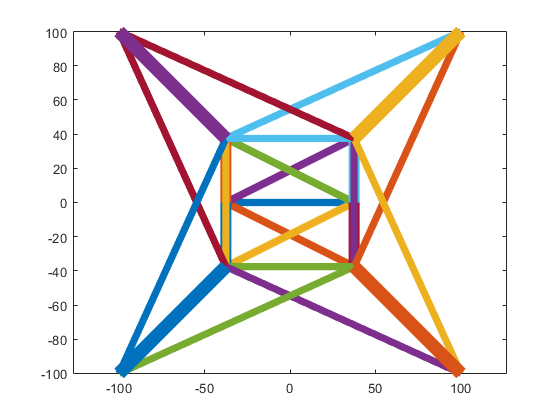

crossSections = reshape(G*value(x), na, nr)'*crossSectionsSet;
nonzeroAreas = value(crossSections)>0;
p = plot([nodes.x(elements.nodes1(nonzeroAreas)) nodes.x(elements.nodes2(nonzeroAreas))]',...
         [nodes.y(elements.nodes1(nonzeroAreas)) nodes.y(elements.nodes2(nonzeroAreas))]');
set(p, {'LineWidth'}, num2cell(10*value(crossSections(nonzeroAreas))/max(value(crossSections))));
xlim([min(nodes.x)-0.1,max(nodes.x)+0.1]);  % To avoid tight limits
ylim([min(nodes.y)-0.1,max(nodes.y)+0.1]);  % To avoid tight limits
axis equal

## Basic FEM

% crossSections = reshape(G*value(x), 10, 5)'*crossSectionsSet;
% 
% staticMatrix(dofs,:)*diag(elements.E.*crossSections./lengths) *staticMatrix(dofs,:)';
% 
% stiffnessMatrix= staticMatrix(dofs,:)* diag(elements.E.*crossSections./lengths) *staticMatrix(dofs,:)';
% displacements = stiffnessMatrix\f;
% y = zeros(ng*na + na*nr+ nd,1);
% y(1:ng*na,1) = x;
% y(1+ng*na:ng*na+nd,1) = displacements;
% y(1+ng*na+nd:ng*na + nr*na+nd,1) = s;
% koo = (Aineq * y <= b)'
% f


## Post-procesing

### Write solution

fprintf('Optimized objective: %f\n', value(objective));

Optimized objective: 604.878242


check(constraints)

 
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|               Constraint|   Primal residual|   Dual residual|         Tag|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Elementwise inequality|       -1.4211e-14|             NaN|   Nerovnost|
|   #2|      Equality constraint|       -9.7249e-14|             NaN|     Rovnost|
|   #3|   Elementwise inequality|                 0|             NaN|   Dolní mez|
|   #4|   Elementwise inequality|                 0|             NaN|   Horní mez|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
| A primal-dual optimal solution would show non-negative residuals.              |
| In practice, many solvers converge to slightly infeasible                      |
| solutions, which may cause some residuals to be negative.                      |
| It is up to the user to judge the importance and impact of                     |
| 

% vector = value(x) .* repmat(1:na, 1, nr)';
% vector(value(x)==1)

### Plotting

Plot the optimal design. Note that the dimensions are scaled.

% crossSections = reshape(value(x), 10, 5)'*crossSectionsSet;
% nonzeroAreas = value(crossSections)>0;
% p = plot([nodes.x(elements.nodes1(nonzeroAreas)) nodes.x(elements.nodes2(nonzeroAreas))]',...
%          [nodes.y(elements.nodes1(nonzeroAreas)) nodes.y(elements.nodes2(nonzeroAreas))]');
% set(p, {'LineWidth'}, num2cell(10*value(crossSections(nonzeroAreas))/max(value(crossSections))));
% xlim([min(nodes.x)-0.1,max(nodes.x)+0.1]);  % To avoid tight limits
% ylim([min(nodes.y)-0.1,max(nodes.y)+0.1]);  % To avoid tight limits
% axis equal

## Basic FEM

% crossSections = reshape(value(x), 10, 5)'*crossSectionsSet;
% 
% staticMatrix(dofs,:)*diag(elements.E.*crossSections./lengths) *staticMatrix(dofs,:)';
% 
% stiffnessMatrix= staticMatrix(dofs,:)* diag(elements.E.*crossSections./lengths) *staticMatrix(dofs,:)';
% displacements = stiffnessMatrix\f;